% 定义变量范围
D = linspace(0.01, 0.5, 100);  % D 的范围从 0 到 0.5
phi = linspace(0, 0.99, 100);  % phi 的范围从 0 到 1

% 创建网格
[D_grid, phi_grid] = meshgrid(D, phi);

% 预分配 M 的矩阵
M = zeros(size(D_grid));

% 计算不同情况下 M 的值
for i = 1:length(phi)
    for j = 1:length(D)
        % 获取当前的 D 和 phi
        D_val = D(j);
        phi_val = phi(i);
        
        % 根据不同的条件计算 M
        if (0 <= phi_val) && (phi_val < 0.5 - D_val)
            M(i,j) = (2*D_val)/(4*D_val+ 4*phi_val - 1);
        elseif (0.5 - D_val <= phi_val) && (phi_val < 0.5)
            M(i,j) = (2*D_val)/(-4*D_val- 4*phi_val +3);
        elseif (0.5 <= phi_val) && (phi_val < 1 - D_val)
            M(i,j) = (2*D_val)/(-4*D_val- 4*phi_val +3);
        elseif (1 - D_val <= phi_val) && (phi_val < 1)
            M(i,j) =(2*D_val)/(4*D_val+ 4*phi_val -5);
        end
    end
end

% % 限制 M 的范围在 0 到 2 之间
 M(M < -2) = -2;
 M(M > 3) = 3;

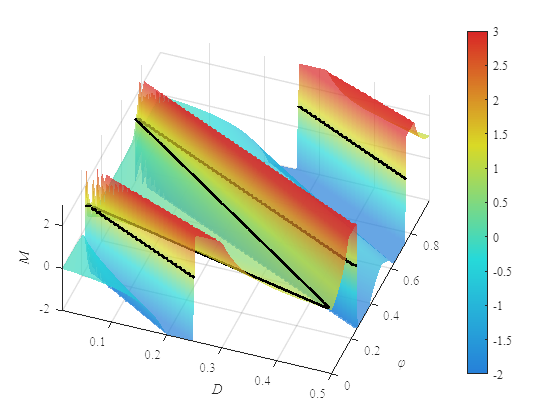

% 绘制3D图
figure;
surf(D_grid, phi_grid, M,'FaceAlpha', 0.7);

% 禁用边框线
set(gca, 'FontName', 'Times New Roman');
%set(gca, 'EdgeColor', 'none'); % 这行可以去掉曲面连接线

% 设置颜色映射
n = 256; % 定义颜色分辨率
cmap = [linspace(0, 0, n/4)', linspace(0.5, 1, n/4)', linspace(1, 1, n/4)'; ... % 蓝到绿
        linspace(0, 1, n/4)', linspace(1, 1, n/4)', linspace(1, 0, n/4)'; ... % 绿到黄
        linspace(1, 1, n/4)', linspace(1, 0, n/4)', linspace(0, 0, n/4)'];    % 黄到红
gray_level = 0.5; % 接近灰色的值（0.5是中性灰）
desaturated_cmap = cmap * 0.7 + gray_level * (1 - 0.7); % 线性插值降低饱和度
colormap(desaturated_cmap);
colorbar;

% 平滑显示
shading interp;  % 平滑插值

% 设置视角和网格
view(20,60); % 设置视角
grid on;
hold on;
% 添加标题和标签
xlabel('\it{D}');
ylabel('\it{φ}');
zlabel('\it{M}');
zlim([-2,3])

% 绘制 M = 1 的平面
% 找到 M = 1 的位置
hold on;
contour3(D_grid, phi_grid, M, [1, 1], 'LineWidth', 2, 'LineColor', 'k');

%text(0.25, 0.2, 1, 'ZVS Region', 'FontSize', 12, 'Color', 'black', 'HorizontalAlignment', 'center');
%text(0.3, 0.15, 0, 'Non-ZVS Region', 'FontSize', 12, 'Color', 'black', 'HorizontalAlignment', 'center');

% 导出为 PDF 格式，设置输出尺寸
%exportgraphics(gcf, 'ZVSLowVoltageSide.pdf', 'ContentType', 'image', 'BackgroundColor', 'none');